%%1번

A=[1 4 2;
   2 4 100;
   7 9 7;
   3 pi 42];
B=log(A);

a1=B(2,:)

a1 =     0.6931    1.3863    4.6052



%---------------------------

b1=sum(a1)

b1 = 6.6846


%------------------------------

c1=B(:,2).*A(:,1)

c1 =     1.3863
    2.7726
   15.3806
    3.4342



%------------------------------

d1=max(c1)

d1 = 15.3806


%------------------------------

e1=A(1,:)./B(1:3,3)'

e1 =     1.4427    0.8686    1.0278


e1_sum=sum(e1)

e1_sum = 3.3391

%%2번

a2_1=50;
a2_2=50;
a2_3=9.81;

a2_4=2*a2_1*sind(a2_2)/a2_3;
a2_5=(a2_1*sind(a2_2))^2/(2*a2_3);
a2_4

a2_4 = 7.8088

a2_5

a2_5 = 74.7737

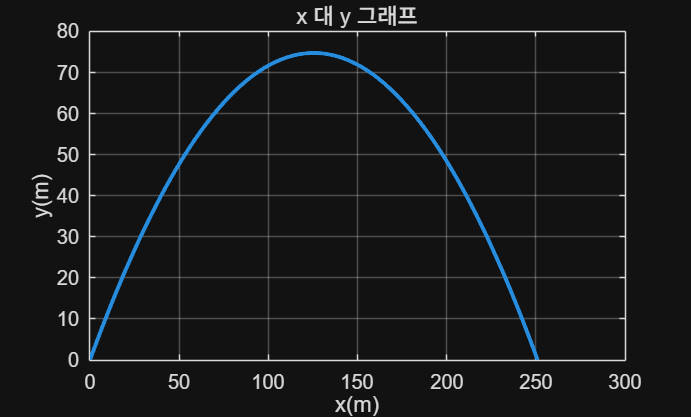


%------------------------------

b2_1=linspace(0,a2_4,1000);
b2_2=(a2_1*cosd(a2_2))*b2_1;
b2_3=(a2_1*sind(a2_2))*b2_1-0.5*a2_3*b2_1.^2;

plot(b2_2,b2_3,'LineWidth',2)
xlabel('x(m)')
ylabel('y(m)')
title('x 대 y 그래프')
grid on

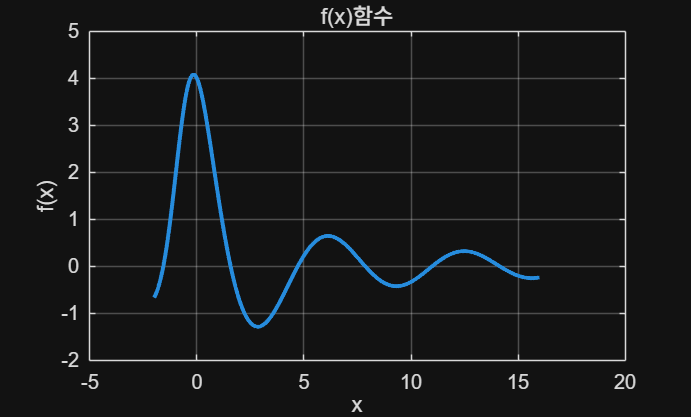

%%3번

a3_1=linspace(-2,16,1000);
a3_2=(4*cos(a3_1))./(a3_1+exp(-0.75*a3_1));

plot(a3_1,a3_2,'LineWidth',2)
xlabel('x')
ylabel('f(x)')
title('f(x)함수')
grid on

%%4번

a4_1=[300;550;400;250;500];
a4_2=[5 4 6;
      3 2 4;
      6 5 3;
      3 5 4;
      2 4 3];
a4_3=a4_1.*a4_2

a4_3 =         1500        1200        1800
        1650        1100        2200
        2400        2000        1200
         750        1250        1000
        1000        2000        1500



%------------------------------

b4_1=sum(a4_3)

b4_1 =         7300        7550        7700



%------------------------------

c4_1=sum(a4_3,2)

c4_1 =         4500
        4950
        5600
        3000
        4500



%------------------------------

d4_1=sum(a4_3(:))

d4_1 = 22550

%%5번

a5_1=[5 0 -3 7 10];
a5_2=[4 -7 9 2];
a5_3=conv(a5_1,a5_2)

a5_3 =     20   -35    33    59   -36   -13   104    20



%------------------------------

b5_1=[5 -7 2 8];
b5_2=[6 3 -2];
b5_3=deconv(b5_1,b5_2)

b5_3 =     0.8333   -1.5833


b5_4=b5_1-conv(b5_2,b5_3)

b5_4 =          0         0    8.4167    4.8333



%------------------------------

c5_1=5;
c5_2=[36 -8 0 2];
c5_3=[36 -5 4 -3];
c5_4=polyval(c5_2,c5_1)/polyval(c5_3,c5_1)

c5_4 = 0.9795

%%7(6)번

a7_1(1).name='Smith St.';
a7_1(1).load=80;
a7_1(1).year=1928;
a7_1(1).limit=2025;

a7_1(2).name='Hope Ave.';
a7_1(2).load=90;
a7_1(2).year=1950;
a7_1(2).limit=2027;

a7_1(3).name='Clark St.';
a7_1(3).load=85;
a7_1(3).year=1933;
a7_1(3).limit=2024;

a7_1(4).name='North Rd.';
a7_1(4).load=100;
a7_1(4).year=1960;
a7_1(4).limit=2023;

%-------------------------------

b7_1=a7_1;
b7_1(3).limit=2026;

%-------------------------------

c7_1=b7_1;

c7_1(5).name='Shore Rd.';
c7_1(5).load=85;
c7_1(5).year=1997;
c7_1(5).limit=2022;


a7_1

a7_1 = 다음 필드를 포함한 1×4 struct 배열:
    name
    load
    year
    limit


b7_1

b7_1 = 다음 필드를 포함한 1×4 struct 배열:
    name
    load
    year
    limit


c7_1

c7_1 = 다음 필드를 포함한 1×5 struct 배열:
    name
    load
    year
    limit
